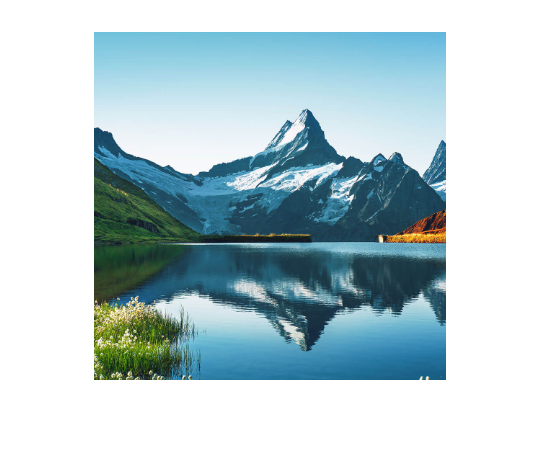

clear
clf

% Input image, the image which will be reproduced
inputImage = imread('Landscape.png');
imshow(inputImage)

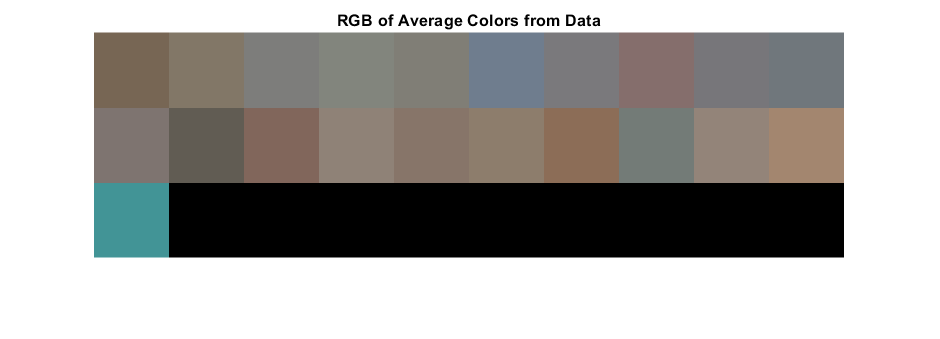


% The data containing all of the smaller images
folder = './data';
fileList = dir(fullfile(folder, '*.jpg'));

% The images are resized to blocksize x blocksize
images = cell(1, numel(fileList));
resized_images = cell(1, numel(fileList));
blocksize = 64;

% Uses showRGB to display all the average colors from the data 
dataBase_avgColors = zeros(numel(fileList), 3);  % Matrix to store average colors (R, G, B)

for i = 1:numel(fileList)
    filename = fullfile(folder, fileList(i).name);
    images{i} = im2double(imread(filename));
    resized_images{i} = imresize(images{i}, [blocksize, blocksize]);
    
    % Calculate average color for each channel (R, G, B)
    dataBase_avgColors(i, 1) = mean(mean(resized_images{i}(:,:,1)));  % Red channel
    dataBase_avgColors(i, 2) = mean(mean(resized_images{i}(:,:,2)));  % Green channel
    dataBase_avgColors(i, 3) = mean(mean(resized_images{i}(:,:,3)));  % Blue channel
end

% Show RGB of average colors from the data
figure;
showRGB(dataBase_avgColors);
title('RGB of Average Colors from Data');

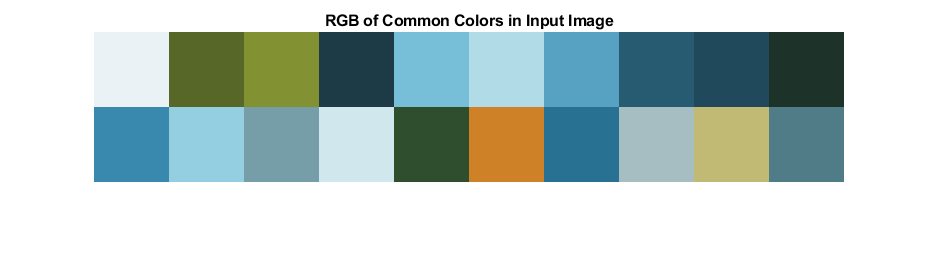


% Convert to XYZ
dataBase_avgColors_xyz = rgb2xyz(dataBase_avgColors);

% Convert the input image to a matrix of RGB values
inputImageSize = size(inputImage);
inputImageMatrix = im2double(reshape(inputImage, [], 3));

% Perform k-means clustering to find the most common colors with increased iterations
num_colors = 20;
opts = statset('MaxIter', 1000);  % Increase the maximum number of iterations
[idx, inputImage_commonColors] = kmeans(inputImageMatrix, num_colors, 'Options', opts);

% Show RGB of common colors in the input image
figure;
showRGB(inputImage_commonColors);
title('RGB of Common Colors in Input Image');


% Convert RGB to XYZ
inputImage_commonColorsXYZ = rgb2xyz(inputImage_commonColors);

